clc
clear
clc
clear
%[m]
cog_B = [0.3; 0; -0.7]; % rear frame
cog_H = [0.9; 0; -0.7]; % front frame + Handle bar
cog_F = [1.02; 0 ;-0.35]; % Front wheel
cog_R = [0; 0; -0.3]; % Rear wheel
%[kg]
mB = 5;
mH = 4;
mF = 3;
mR = 2;
%[kg*m^2]
IB = [9.2 0 2.4;
      0 11 0;
      2.4 0 2.8]/17;
IH = [0.05892 0 -0.00756;
      0 0.06 0;
      -0.00756 0 0.00708];
IF = [0.1405 0 0;
      0 0.28 0;
      0 0 0];
IR = [0.0603 0 0;
      0 0.12 0;
      0 0 0];
g = 9.81;%[m/s^2]
Rr = 0.3;%[m]
Rf = 0.35; %[m]



% Combine bodies B and H
[cog_BH, combinedMass_BH, combinedInertia_BH] = combineInertia(cog_B, cog_H, mB, mH, IB, IH)

cog_BH =     0.5667
         0
   -0.7000


combinedMass_BH = 9

combinedInertia_BH =     0.6001   -0.8000   -0.6664
   -0.8000    0.7071   -0.8000
   -0.6664   -0.8000    0.1718



% Combine bodies BH and F
[cog_BHF, combinedMass_BHF, combinedInertia_BHF] = combineInertia(cog_BH, cog_F, combinedMass_BH, mF, combinedInertia_BH, IF);

% Combine bodies BHF and R
[cog_BHFR, combinedMass_BHFR, combinedInertia_BHFR] = combineInertia(cog_BHF, cog_R, combinedMass_BHF, mR, combinedInertia_BHF, IR);


cog_Bike = cog_BHFR

cog_Bike =     0.5829
         0
   -0.5679


m_Bike = combinedMass_BHFR

m_Bike = 14

inertia_Bike = combinedInertia_BHFR

inertia_Bike =     0.8009   -2.4981   -2.3645
   -2.4981    1.1071   -2.4981
   -2.3645   -2.4981    0.1718


mf = 2.02;
mb = m_Bike;

hb = -cog_Bike(3)

hb = 0.5679

hf= 0.9

hf = 0.9000

Ib = inertia_Bike(1,1)

Ib = 0.8009

Ip = 0.0088

Ip = 0.0088

Ir = 0.0224

Ir = 0.0224

w = 469

w = 469

L = 0.000119

L = 1.1900e-04

R = 0.61

R = 0.6100

Bm = 0.003

Bm = 0.0030

Km = 0.0259

Km = 0.0259

Ke = 0.0027

Ke = 0.0027

g = 9.81

g = 9.8100

A =[ 0 1 0 0;
    g*(mb*hb+mf*hf)/(mb*hb^2+mf*hf^2+Ib + Ir) 0 Ip*w/(mb*hb^2+mf*hf^2+Ib + Ir) 0;
    0 -Ip*w/Ir -Bm/Ir 65*Km/Ir;
    0 0 -Ke/L -R/L];
B = [0;0;0;1/L];
C = [1 0 0 0];
D = 0;
system= ss(A,B,C,D) % uncompensated systeemtem (no controller)


system =
 
  A = 
            x1       x2       x3       x4
   x1        0        1        0        0
   x2    13.74        0   0.5918        0
   x3        0   -184.3  -0.1339    75.16
   x4        0        0   -22.69    -5126
 
  B = 
         u1
   x1     0
   x2     0
   x3     0
   x4  8403
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



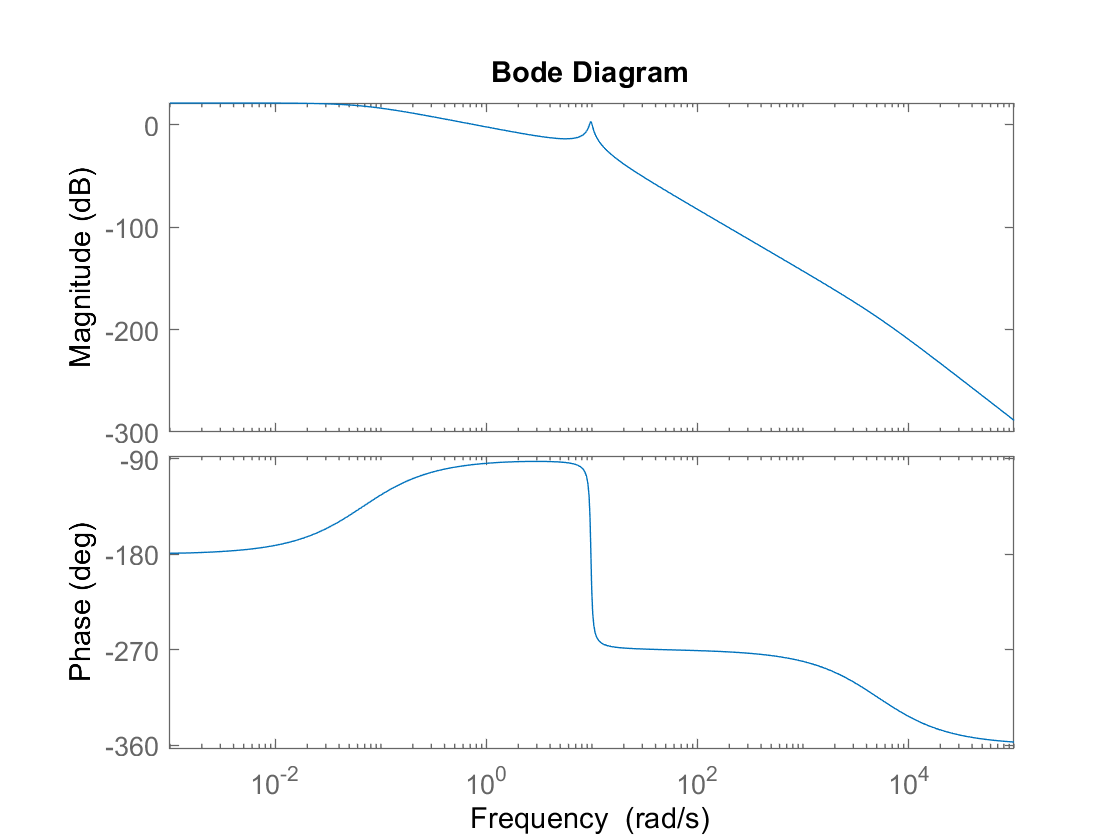


bode(system)

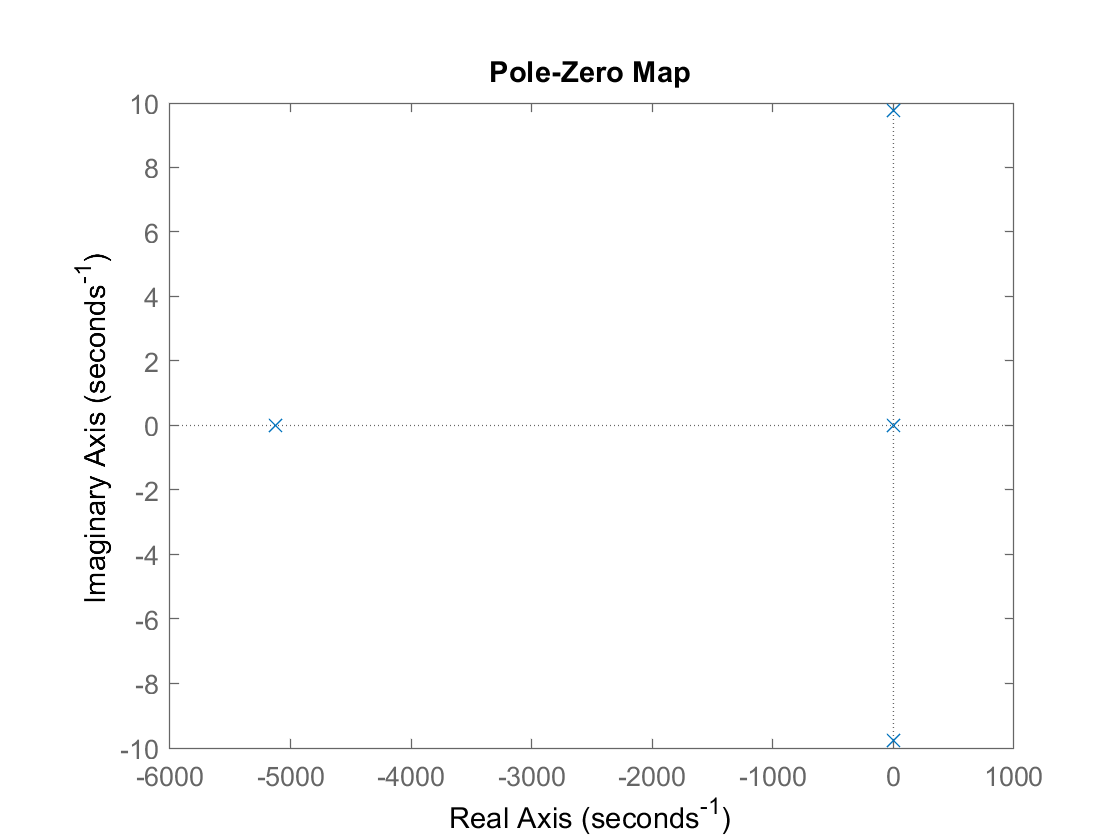

pzmap(system)

[num,den]=ss2tf(A,B,C,D)

num = 	1.0e+05 *

         0         0         0         0    3.7376


den = 	1.0e+05 *

    0.0000    0.0513    0.0249    4.8851   -0.3286


tfunction= tf(num,den)


tfunction =
 
                      3.738e05
  -------------------------------------------------
  s^4 + 5126 s^3 + 2487 s^2 + 4.885e05 s - 3.286e04
 
Continuous-time transfer function.




load PIDF2.mat;
PIDF2


PIDF2 =
 
             1            s    
  Kp + Ki * --- + Kd * --------
             s          Tf*s+1 

  with Kp = 1.75, Ki = 0.231, Kd = -0.486, Tf = 0.277
 
Continuous-time PIDF controller in parallel form.




compensatedsys=PIDF2*tfunction;

fb =feedback(compensatedsys,1)


fb =
 
                                 2.45e06 s + 3.114e05
  ----------------------------------------------------------------------------------
  s^6 + 5130 s^5 + 2.099e04 s^4 + 4.975e05 s^3 + 1.73e06 s^2 + 2.331e06 s + 3.114e05
 
Continuous-time transfer function.



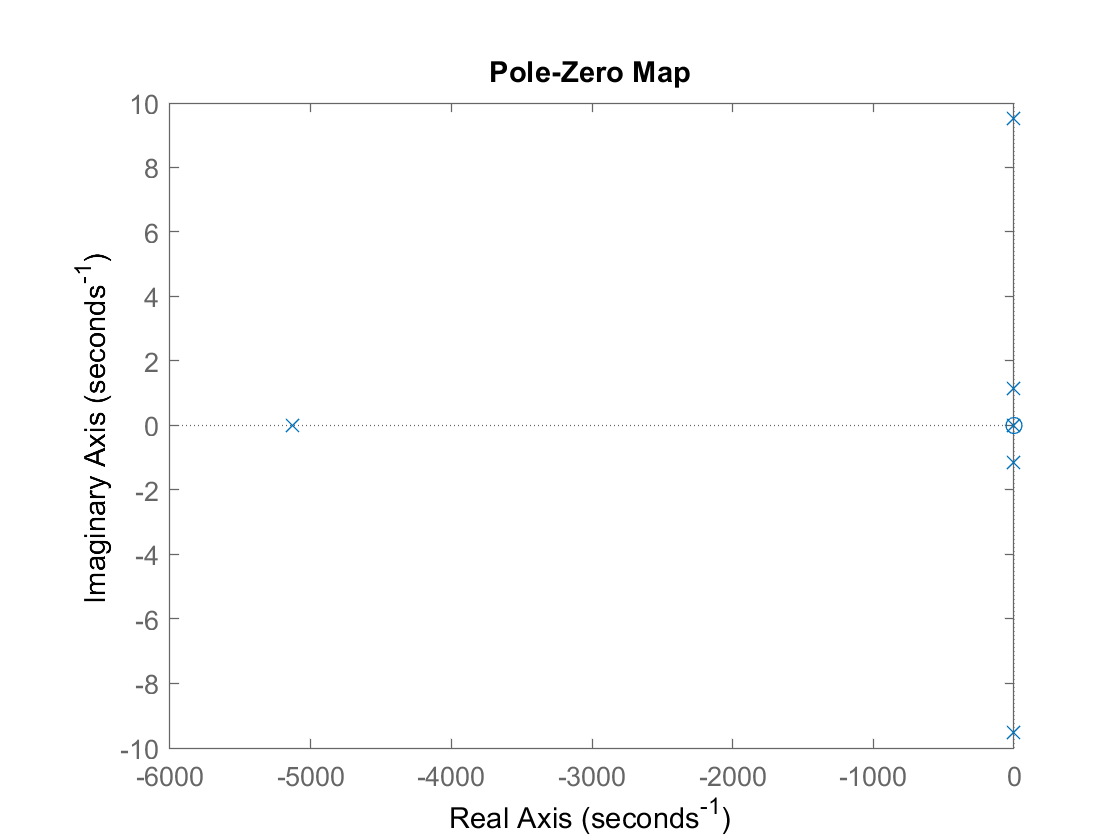

figure
pzmap(fb)

u= zeros(1,10000);
t = [0:1:9999]./100

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


u(1:1000)= 1

u =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


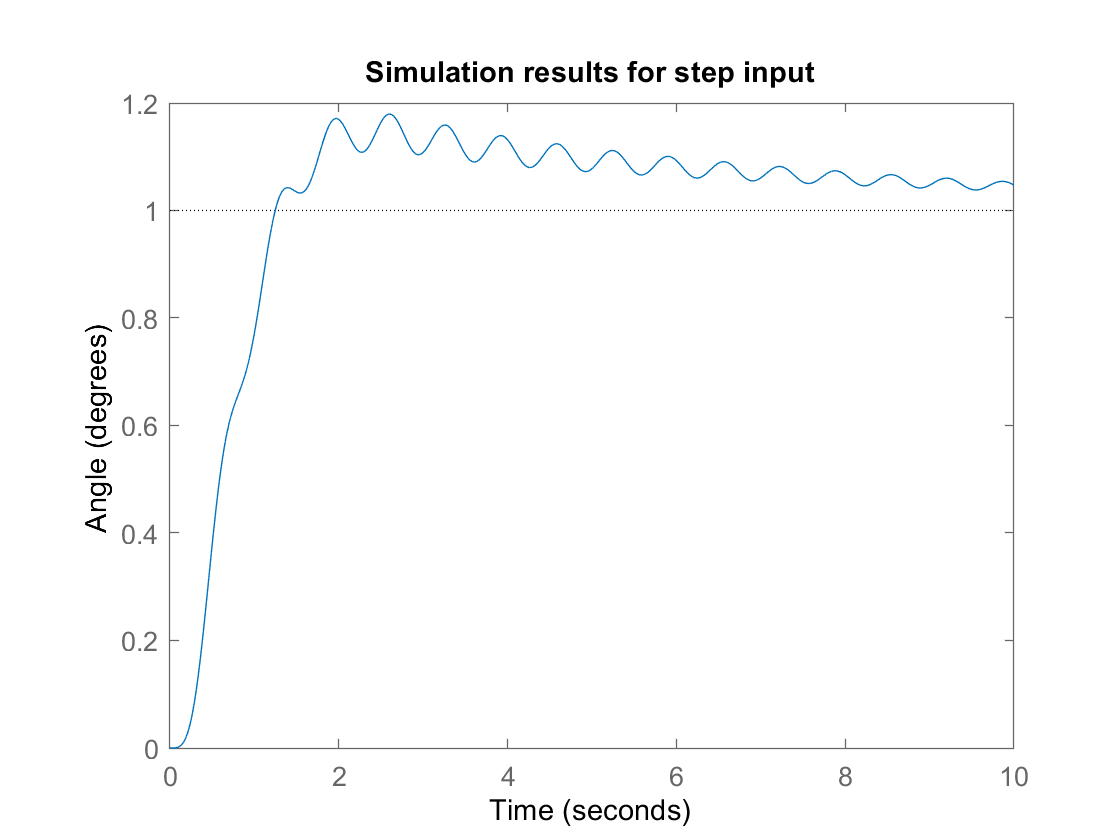

step(fb)
xlim([0,10])
ylabel('Angle (degrees)')
title('Simulation results for step input')

fb2=fb


fb2 =
 
                                 2.45e06 s + 3.114e05
  ----------------------------------------------------------------------------------
  s^6 + 5130 s^5 + 2.099e04 s^4 + 4.975e05 s^3 + 1.73e06 s^2 + 2.331e06 s + 3.114e05
 
Continuous-time transfer function.



function [combinedCOG, totalMass, combinedInertia] = combineInertia(cog1, cog2, mass1, mass2, inertia1, inertia2)
    % Check if the matrices are of correct dimensions
    if any(size(cog1) ~= size(cog2)) || any(size(inertia1) ~= size(inertia2))
        error('Invalid input dimensions. Make sure the inputs are consistent.');
    end

    % Calculate the combined center of gravity
    totalMass = mass1 + mass2;
    combinedCOG = (cog1 * mass1 + cog2 * mass2) / totalMass; % FORMULA COG = Sum(RxM)/Sum(M)

    % Calculate the translation vectors for each body
    translation1 = combinedCOG - cog1;
    translation2 = combinedCOG - cog2;

    % Apply Steiner's theorem to combine moments of inertia
    
    combinedInertia = inertia1 + mass1 * (translation1.' * translation1 * eye(3) - translation1.' * translation1) + ...
                  inertia2 + mass2 * (translation2.' * translation2 * eye(3) - translation2.' * translation2);

end









